## Simulink

Parametres from Cheng

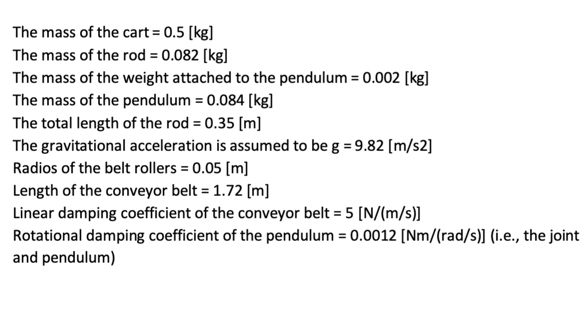

m_c = 0.5;      % Mass of cart [kg]
m_p = 0.083;    % Mass of pendulum [kg]
l = 0.357;      % Length of pendulum [m]
g = 9.81;       % Gravitational acceleration [m/s^2]
b_c = 5;        % Linear damping coefficient of the cart [N/(m/s)]
b_p = 0.0012;   % Rotational damping coefficient of the pendulum [Nm/(rad/s)
I = (1/3)*m_p*l^2;     % inertia of pendulum



function [xdd, thetadd] = fcn(m_c, m_p, l, b_c, b_p, I, g, xd, x, thetad, theta, F)

% Masse-matrix
M = [m_c + m_p,  mp*l*cos(theta);
     m_p * l * cos(theta), mp * l^2 + I]
M_inv = inv(M)

% Højre side af ligningen
RHS = [F - b_c * xd + m_p * l * sin(theta) * thetad^2;
       -b_p * thetad - mp*g*l*sin(theta)]

a = M_inv*RHS

xdd = a(1)
thetadd = a(2)


end

## Isolering af ddx og ddtheta

% Symbolsk variabler
syms mc mp l theta thetad thetadd x xd xdd I bc bp g F

% Masse-matrix
M = [mc + mp,  mp*l*cos(theta);
     mp*l*cos(theta), mp*l^2 + I]

$$M = \left(\begin{array}{cc} \mathrm{mc}+\mathrm{mp} & l\,\mathrm{mp}\,\cos\left(\theta \right)\\ l\,\mathrm{mp}\,\cos\left(\theta \right) & \mathrm{mp}\,l^{2}+\text{I} \end{array}\right)$$

M_inv = inv(M)

$$M\_inv = \begin{array}{l} \left(\begin{array}{cc} \frac{\mathrm{mp}\,l^{2}+\text{I}}{\sigma_{1}} & -\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)}{\sigma_{1}}\\ -\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)}{\sigma_{1}} & \frac{\mathrm{mc}+\mathrm{mp}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,{\mathrm{mp}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\mathrm{mp}}^{2}+\mathrm{mc}\,l^{2}\,\mathrm{mp}+\text{I}\,\mathrm{mp}+\text{I}\,\mathrm{mc} \end{array}$$


% Højre side af ligningen
RHS = [F - bc*xd + mp*l*sin(theta)*thetad^2;
       -bp*thetad - mp*g*l*sin(theta)]

$$RHS = \left(\begin{array}{c} l\,\mathrm{mp}\,\sin\left(\theta \right)\,{\mathrm{thetad}}^{2}+F-\mathrm{bc}\,\mathrm{xd}\\ -\mathrm{bp}\,\mathrm{thetad}-g\,l\,\mathrm{mp}\,\sin\left(\theta \right) \end{array}\right)$$


a = M_inv*RHS

$$a = \begin{array}{l} \left(\begin{array}{c} \frac{\left(\mathrm{mp}\,l^{2}+\text{I}\right)\,\sigma_{2}}{\sigma_{1}}+\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)\,\left(\mathrm{bp}\,\mathrm{thetad}+g\,l\,\mathrm{mp}\,\sin\left(\theta \right)\right)}{\sigma_{1}}\\ -\frac{\left(\mathrm{bp}\,\mathrm{thetad}+g\,l\,\mathrm{mp}\,\sin\left(\theta \right)\right)\,\left(\mathrm{mc}+\mathrm{mp}\right)}{\sigma_{1}}-\frac{l\,\mathrm{mp}\,\cos\left(\theta \right)\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,{\mathrm{mp}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\mathrm{mp}}^{2}+\mathrm{mc}\,l^{2}\,\mathrm{mp}+\text{I}\,\mathrm{mp}+\text{I}\,\mathrm{mc}\\ \sigma_{2}=l\,\mathrm{mp}\,\sin\left(\theta \right)\,{\mathrm{thetad}}^{2}+F-\mathrm{bc}\,\mathrm{xd} \end{array}$$

simplifiedExpr = simplify(a)

$$simplifiedExpr = \begin{array}{l} \left(\begin{array}{c} \frac{F\,\text{I}-\text{I}\,\mathrm{bc}\,\mathrm{xd}+F\,l^{2}\,\mathrm{mp}-\mathrm{bc}\,l^{2}\,\mathrm{mp}\,\mathrm{xd}+l^{3}\,{\mathrm{mp}}^{2}\,{\mathrm{thetad}}^{2}\,\sin\left(\theta \right)+g\,l^{2}\,{\mathrm{mp}}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)+\text{I}\,l\,\mathrm{mp}\,{\mathrm{thetad}}^{2}\,\sin\left(\theta \right)+\mathrm{bp}\,l\,\mathrm{mp}\,\mathrm{thetad}\,\cos\left(\theta \right)}{\sigma_{1}}\\ -\frac{\mathrm{bp}\,\mathrm{mc}\,\mathrm{thetad}+\mathrm{bp}\,\mathrm{mp}\,\mathrm{thetad}+F\,l\,\mathrm{mp}\,\cos\left(\theta \right)+g\,l\,{\mathrm{mp}}^{2}\,\sin\left(\theta \right)+l^{2}\,{\mathrm{mp}}^{2}\,{\mathrm{thetad}}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)-\mathrm{bc}\,l\,\mathrm{mp}\,\mathrm{xd}\,\cos\left(\theta \right)+g\,l\,\mathrm{mc}\,\mathrm{mp}\,\sin\left(\theta \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,{\mathrm{mp}}^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,{\mathrm{mp}}^{2}+\mathrm{mc}\,l^{2}\,\mathrm{mp}+\text{I}\,\mathrm{mp}+\text{I}\,\mathrm{mc} \end{array}$$

disp('----------------------------------------------------------')

----------------------------------------------------------


## State space -> transfer function

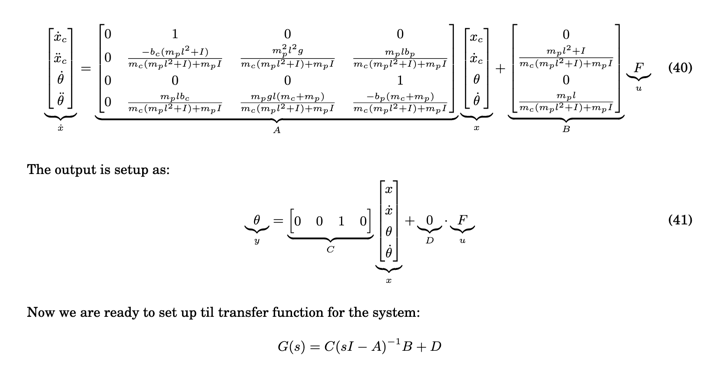

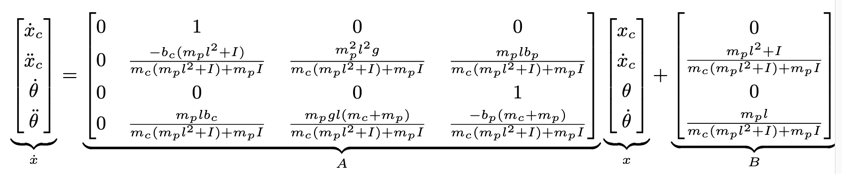

clc; clear; close all;

%syms b_c b_p m_c m_p l_p I g l 
syms s z

m_c = 0.5;      % Masse af vognen (kg)
m_p = 0.083;    % Masse af pendulet (kg) *
l = 0.357;      % Pendulets længde (m) *
g = 9.81;       % Tyngdeacceleration (m/s^2)
b_c = 0.1;      % Dæmpning på vognen
b_p = 0.001;    % Dæmpning på pendulet
k = 0.5;        % fjeder i bånd
I = (1/3)*m_p*l^2     % inerti af pendum

I = 0.0035

g = 9.81;

% Definer matrixen
A = [0, 1, 0, 0;
     0, (-b_c * (m_p*l^2 + I)) / (m_c*(m_p*l^2 + I) + m_p*I), (m_p^2*l^2*g)/(m_c*(m_p*l^2 + I) + m_p*I), (m_p*l*b_p)/(m_c*(m_p*l^2 + I) + m_p*I);
     0, 0, 0, 1;
     0, (m_p*l*b_c)/(m_c*(m_p*l^2 + I) + m_p*I), (m_p*g*l*(m_c + m_p))/(m_c*(m_p*l^2 + I) + m_p*I), (-b_p*(m_c + m_p))/(m_c*(m_p*l^2 + I) + m_p*I)];
%disp(A)

B = [ 0;
     (m_p*l^2 + I) / (m_c*(m_p*l^2 + I) + m_p*I);
      0;
      (m_p*l) / (m_c*(m_p*l^2 + I) + m_p*I) ];
%disp(B)

C = [1 0 0 0;
     0 0 1 0];

D = [0; 0];

disp('----------------------------------------------------------')

----------------------------------------------------------


disp('Grov løsning med dum formel')

Grov løsning med dum formel


Gs = C*inv(s*eye(4)-A)*B+D;

myTf = simplify(Gs);
x = myTf(1);
theta = myTf(2);
disp('Transfer function for x')

Transfer function for x


disp(x)

$$-\frac{32\,\left(649037107316853453566312041152512000\,s^{2}+57018396639666805636222435705782031\,s-13376163913399861213482518152306584448\right)}{s\,\left(-10815554356328045950229023853765459968\,s^{3}-2935407870751841391742277454422605824\,s^{2}+249398460258724363000850280132851708349\,s+53037164183174333002933806405350700416\right)}$$


disp('Transfer function for theta')

Transfer function for theta


disp(theta)

$$-\frac{18446744073709551616\,\left(2365335938745008717\,s+908434349974079225\right)}{-10815554356328045950229023853765459968\,s^{3}-2935407870751841391742277454422605824\,s^{2}+249398460258724363000850280132851708349\,s+53037164183174333002933806405350700416}$$



disp('----------------------------------------------------------')

----------------------------------------------------------


disp('Forenklet løsning via matlab funktioner')

Forenklet løsning via matlab funktioner


states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)


sys_ss =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot              0     -0.192      1.173   0.004034
   theta              0          0          0          1
   theta_dot          0     0.4034      23.07   -0.07938
 
  B = 
                  u
   x              0
   x_dot       1.92
   theta          0
   theta_dot  4.034
 
  C = 
                  x      x_dot      theta  theta_dot
   x              1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.


sys_tf = tf(sys_ss)


sys_tf =
 
  From input "u" to output...
            1.92 s^2 + 0.1687 s - 39.58
   x:  --------------------------------------
       s^4 + 0.2714 s^3 - 23.06 s^2 - 4.904 s
 
                    4.034 s + 1.549
   theta:  ----------------------------------
           s^3 + 0.2714 s^2 - 23.06 s - 4.904
 
Continuous-time transfer function.
Model Properties


x = sys_tf(1)


x =
 
  From input "u" to output "x":
       1.92 s^2 + 0.1687 s - 39.58
  --------------------------------------
  s^4 + 0.2714 s^3 - 23.06 s^2 - 4.904 s
 
Continuous-time transfer function.
Model Properties


theta = sys_tf(2)


theta =
 
  From input "u" to output "theta":
           4.034 s + 1.549
  ----------------------------------
  s^3 + 0.2714 s^2 - 23.06 s - 4.904
 
Continuous-time transfer function.
Model Properties
